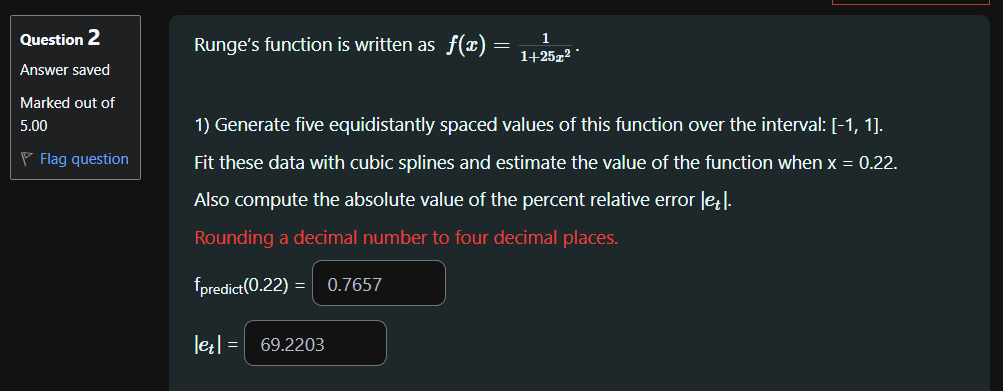

x = linspace(-1,1,5)

x =    -1.0000   -0.5000         0    0.5000    1.0000


y = 1./(1+25.*x.^2)

y =     0.0385    0.1379    1.0000    0.1379    0.0385



xx = linspace(-1,1)

xx =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


yy = 1./(1+25.*xx.^2)

yy =     0.0385    0.0400    0.0416    0.0434    0.0452    0.0472    0.0492    0.0515    0.0538    0.0564    0.0591    0.0620    0.0652    0.0685    0.0722    0.0761    0.0803    0.0849    0.0899    0.0953    0.1012    0.1077    0.1147    0.1225    0.1310    0.1404    0.1507    0.1622    0.1749    0.1891    0.2049    0.2226    0.2424    0.2647    0.2897    0.3179    0.3497    0.3855    0.4256    0.4706    0.5206    0.5756    0.6354    0.6988    0.7642    0.8288    0.8889    0.9401    0.9776    0.9975


% plot(xx,yy,'b--')
hold on
plot(x,y,'m*')

yyspline = spline(x,y,xx)

yyspline =     0.0385   -0.0195   -0.0704   -0.1145   -0.1520   -0.1831   -0.2081   -0.2273   -0.2408   -0.2490   -0.2521   -0.2503   -0.2438   -0.2330   -0.2180   -0.1992   -0.1767   -0.1508   -0.1218   -0.0898   -0.0552   -0.0182    0.0210    0.0621    0.1049    0.1491    0.1945    0.2408    0.2879    0.3353    0.3830    0.4306    0.4780    0.5248    0.5708    0.6157    0.6594    0.7016    0.7420    0.7804    0.8166    0.8502    0.8811    0.9089    0.9336    0.9547    0.9721    0.9855    0.9947    0.9994


hold on
plot(xx,yyspline,'g-')


x_test = 0.22;
y_pred = spline(x,y,x_test)

y_pred = 0.7657

true = 1./(1+25.*x_test.^2)

true = 0.4525

et = abs(((true - y_pred)/true)*100)

et = 69.2203

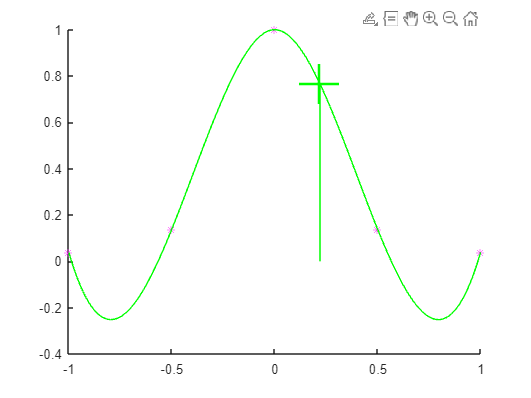

plot(x_test, y_pred, 'g+', 'LineWidth', 2, 'MarkerSize', 30);
hold on
line([x_test, x_test], [0, y_pred], 'Color', 'g');
hold off

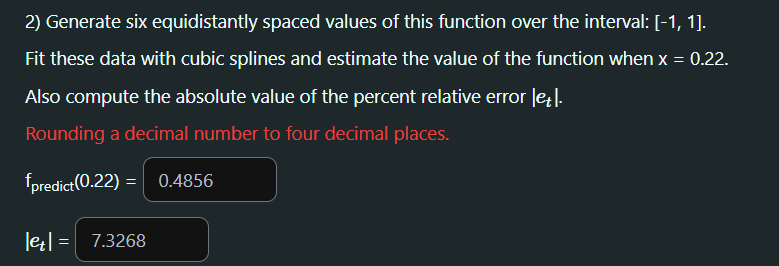

x = linspace(-1,1,6)

x =    -1.0000   -0.6000   -0.2000    0.2000    0.6000    1.0000


y = 1./(1+25.*x.^2)

y =     0.0385    0.1000    0.5000    0.5000    0.1000    0.0385



xx = linspace(-1,1)

xx =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


yy = 1./(1+25.*xx.^2)

yy =     0.0385    0.0400    0.0416    0.0434    0.0452    0.0472    0.0492    0.0515    0.0538    0.0564    0.0591    0.0620    0.0652    0.0685    0.0722    0.0761    0.0803    0.0849    0.0899    0.0953    0.1012    0.1077    0.1147    0.1225    0.1310    0.1404    0.1507    0.1622    0.1749    0.1891    0.2049    0.2226    0.2424    0.2647    0.2897    0.3179    0.3497    0.3855    0.4256    0.4706    0.5206    0.5756    0.6354    0.6988    0.7642    0.8288    0.8889    0.9401    0.9776    0.9975


% plot(xx,yy,'b--')

plot(x,y,'m*')
hold on
yyspline = spline(x,y,xx)

yyspline =     0.0385    0.0196    0.0038   -0.0091   -0.0192   -0.0267   -0.0316   -0.0340   -0.0342   -0.0321   -0.0280   -0.0218   -0.0138   -0.0040    0.0074    0.0203    0.0346    0.0503    0.0671    0.0850    0.1038    0.1235    0.1439    0.1650    0.1865    0.2084    0.2306    0.2529    0.2753    0.2976    0.3197    0.3415    0.3629    0.3838    0.4040    0.4235    0.4420    0.4597    0.4762    0.4915    0.5054    0.5180    0.5292    0.5389    0.5473    0.5543    0.5599    0.5641    0.5669    0.5683


hold on
plot(xx,yyspline,'g-')


x_test = 0.22;
y_pred = spline(x,y,x_test)

y_pred = 0.4856

true = 1./(1+25.*x_test.^2);
et = abs(((true - y_pred)/true)*100)

et = 7.3268

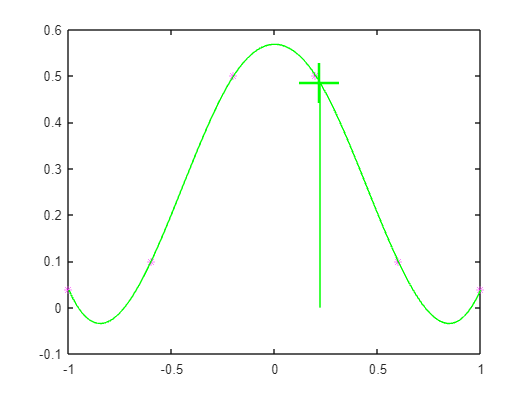

hold on
plot(x_test, y_pred, 'g+', 'LineWidth', 2, 'MarkerSize', 30);
line([x_test, x_test], [0, y_pred], 'Color', 'g');
hold off

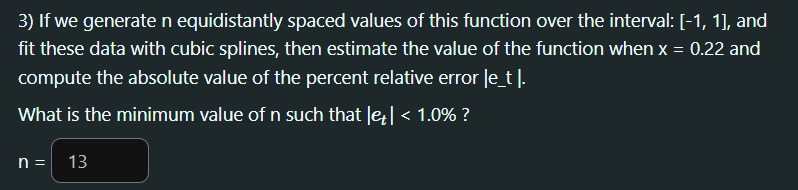

x = linspace(-1,1,13)

x =    -1.0000   -0.8333   -0.6667   -0.5000   -0.3333   -0.1667         0    0.1667    0.3333    0.5000    0.6667    0.8333    1.0000


y = 1./(1+25.*x.^2)

y =     0.0385    0.0545    0.0826    0.1379    0.2647    0.5902    1.0000    0.5902    0.2647    0.1379    0.0826    0.0545    0.0385



xx = linspace(-1,1)

xx =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


yy = 1./(1+25.*xx.^2)

yy =     0.0385    0.0400    0.0416    0.0434    0.0452    0.0472    0.0492    0.0515    0.0538    0.0564    0.0591    0.0620    0.0652    0.0685    0.0722    0.0761    0.0803    0.0849    0.0899    0.0953    0.1012    0.1077    0.1147    0.1225    0.1310    0.1404    0.1507    0.1622    0.1749    0.1891    0.2049    0.2226    0.2424    0.2647    0.2897    0.3179    0.3497    0.3855    0.4256    0.4706    0.5206    0.5756    0.6354    0.6988    0.7642    0.8288    0.8889    0.9401    0.9776    0.9975


% plot(xx,yy,'b--')

plot(x,y,'m*')
hold on
yyspline = spline(x,y,xx)

yyspline =     0.0385    0.0401    0.0418    0.0436    0.0454    0.0473    0.0494    0.0515    0.0539    0.0564    0.0590    0.0619    0.0651    0.0685    0.0721    0.0761    0.0803    0.0849    0.0899    0.0953    0.1012    0.1076    0.1147    0.1225    0.1310    0.1403    0.1506    0.1619    0.1746    0.1888    0.2047    0.2225    0.2424    0.2647    0.2895    0.3174    0.3487    0.3841    0.4239    0.4687    0.5189    0.5751    0.6375    0.7039    0.7709    0.8352    0.8934    0.9421    0.9779    0.9974


hold on
plot(xx,yyspline,'g-')


x_test = 0.22;
y_pred = spline(x,y,x_test)

y_pred = 0.4506

true = 1./(1+25.*x_test.^2);
et = abs(((true - y_pred)/true)*100)

et = 0.4240

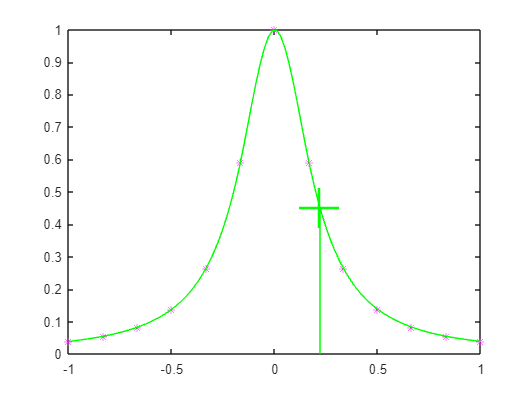

hold on
plot(x_test, y_pred, 'g+', 'LineWidth', 2, 'MarkerSize', 30);
line([x_test, x_test], [0, y_pred], 'Color', 'g');
hold off

Data 

% % x = [1 3 4.5 6 8 11 13 14];
% % y = [2 3 3.5 2.8 4 3.5 3.4 3];
% 
% x = linspace(-1,1,5);
% % x = [3.0 4.5 7.0 9.0 11.0];
% y = 1./(1+25.*x.^2)
% % y = [2.5 1.0 2.5 0.5 2.0];
% 
% plot(x,y,'ko')
% hold on
% % axis([-2 18 0 6])

Linear spline

% % xx = -1 : 0.1 : 1;
% % yy = interp1(x,y,xx,"linear")
% % 
% % 
% % plot(x,y,'ko')
% % hold on
% % 
% % plot(xx,yy,'r-')
% % hold off
% % axis([0 14 -1 5])

Quadratic spline

% % xx = 1 : 0.1 : 14
% % yy = quspline(x,y,xx)
% % 
% % plot(x,y,'ko')
% % hold on
% % 
% % plot(xx,yy,'r-')
% % hold off
% % axis([-2 18 1 6])

Cubic spline (natural spline)

% % xx = -1 : 0.01 : 1;
% % yy = natspline(x,y,xx)
% % yy = interp1(x,y,xx,"spline")
% % pp = spline(x,y)
% % 
% % % 
% % [~, coeffs] = unmkpp(pp);
% % coeffs(2, :)
% % %
% % 
% % plot(x,y,'ko')
% % hold on
% % 
% % plot(xx,yy,'r-')
% % hold off
% % axis([0 14 -1 5])
% 
% 

Cubic spline (using interp1)

% xx = 3 : 0.1 : 11;
% % yy = natspline(x,y,xx)
% yy = interp1(x,y,xx,"spline")
% 
% pp = spline(x,y)
% 
% % 
% [~, coeffs] = unmkpp(pp);
% coeffs(1, :)
% %
% 
% plot(x,y,'ko')
% hold on
% 
% plot(xx,yy,'r-')
% hold off
% % axis([0 14 -1 5])
% 
% x_test = 10;
% y_pred = spline(x,y,x_test)

Cubic spline (using spline)

% xx = 3 : 0.1 : 11;
% % yy = natspline(x,y,xx)
% yy = spline(x,y,xx)
% 
% 
% plot(x,y,'ko')
% hold on
% 
% plot(xx,yy,'r-')
% hold off
% axis([0 14 -1 5])

Cubic spline (using spline & ppval)

% xx = 3 : 0.1 : 11;
% cs = spline(x,y)
% yy = ppval(cs,xx)
% 
% 
% plot(x,y,'ko')
% hold on
% 
% plot(xx,yy,'r-')
% hold off
% axis([0 14 -1 5])

Cubic spline (plot each segment with different colors)

% seg1 = linspace(x(1),x(2))
% seg2 = linspace(x(2),x(3))
% seg3 = linspace(x(3),x(4))
% seg4 = linspace(x(4),x(5))
% % seg5 = linspace(x(5),x(6))
% % seg6 = linspace(x(6),x(7))
% % seg7 = linspace(x(7),x(8))
% 
% yseg1 = spline(x,y,seg1);
% yseg2 = spline(x,y,seg2);
% yseg3 = spline(x,y,seg3);
% yseg4 = spline(x,y,seg4);
% % yseg5 = spline(x,y,seg5);
% % yseg6 = spline(x,y,seg6);
% % yseg7 = spline(x,y,seg7);
% 
% plot(x,y,'ko')
% 
% hold on
% plot(seg1,yseg1,'r-')
% plot(seg2,yseg2,'g-')
% plot(seg3,yseg3,'b-')
% plot(seg4,yseg4,'r-')
% % plot(seg5,yseg5,'g-')
% % plot(seg6,yseg6,'b-')
% % plot(seg7,yseg7,'r-')
% hold off
% 
% axis([0 14 -1 5])
% 